### **Chapter 4: Gettin in on the action**

Alright, as a brand new contributor we have cloned a project and not only gotten a good feel for the quality and level of investment the author put into this project, but we have also have been able to contribute meaningfully to its quality. We were able to get up and running building all the artifacts needed to run the unit tests, and didn't need any prior knowledge because the build tool handled it all for us. Before really get going, it would be great to ensure that we check in our changes and "do no harm".

A good rule of thumb here, just like one might invoke the default `make` target when working with Makefiles, is to run the default build target for the MATLAB build. Let's do that and see what the build does. Just invoke the buildtool with no task. It will run the default tasks. Invoke buildtool in the command window: 

Here you can see a few things:

- It ran some other tasks we haven't met yet. It p-coded some files, created HTML doc files from mlx examples and the Getting Sarted guide, and it produced an mltbx toolbox package and ran integration tests on it.

- It also didn't run some tasks that we have already met. It didnt run them because it didn't need to. We haven't made any changes so no need to compile mex files or even run the unit tests again. Now that you have gone through this default build go ahead and run it again and see what happens:

Nothing! We've done all the work and so now all we need is to submit it. It should be good to go.

Le'ts get back to the project and then commit and push! (If you are having troubles here, did you do the homework? You need to be able to commit back to your repo from MATLAB)

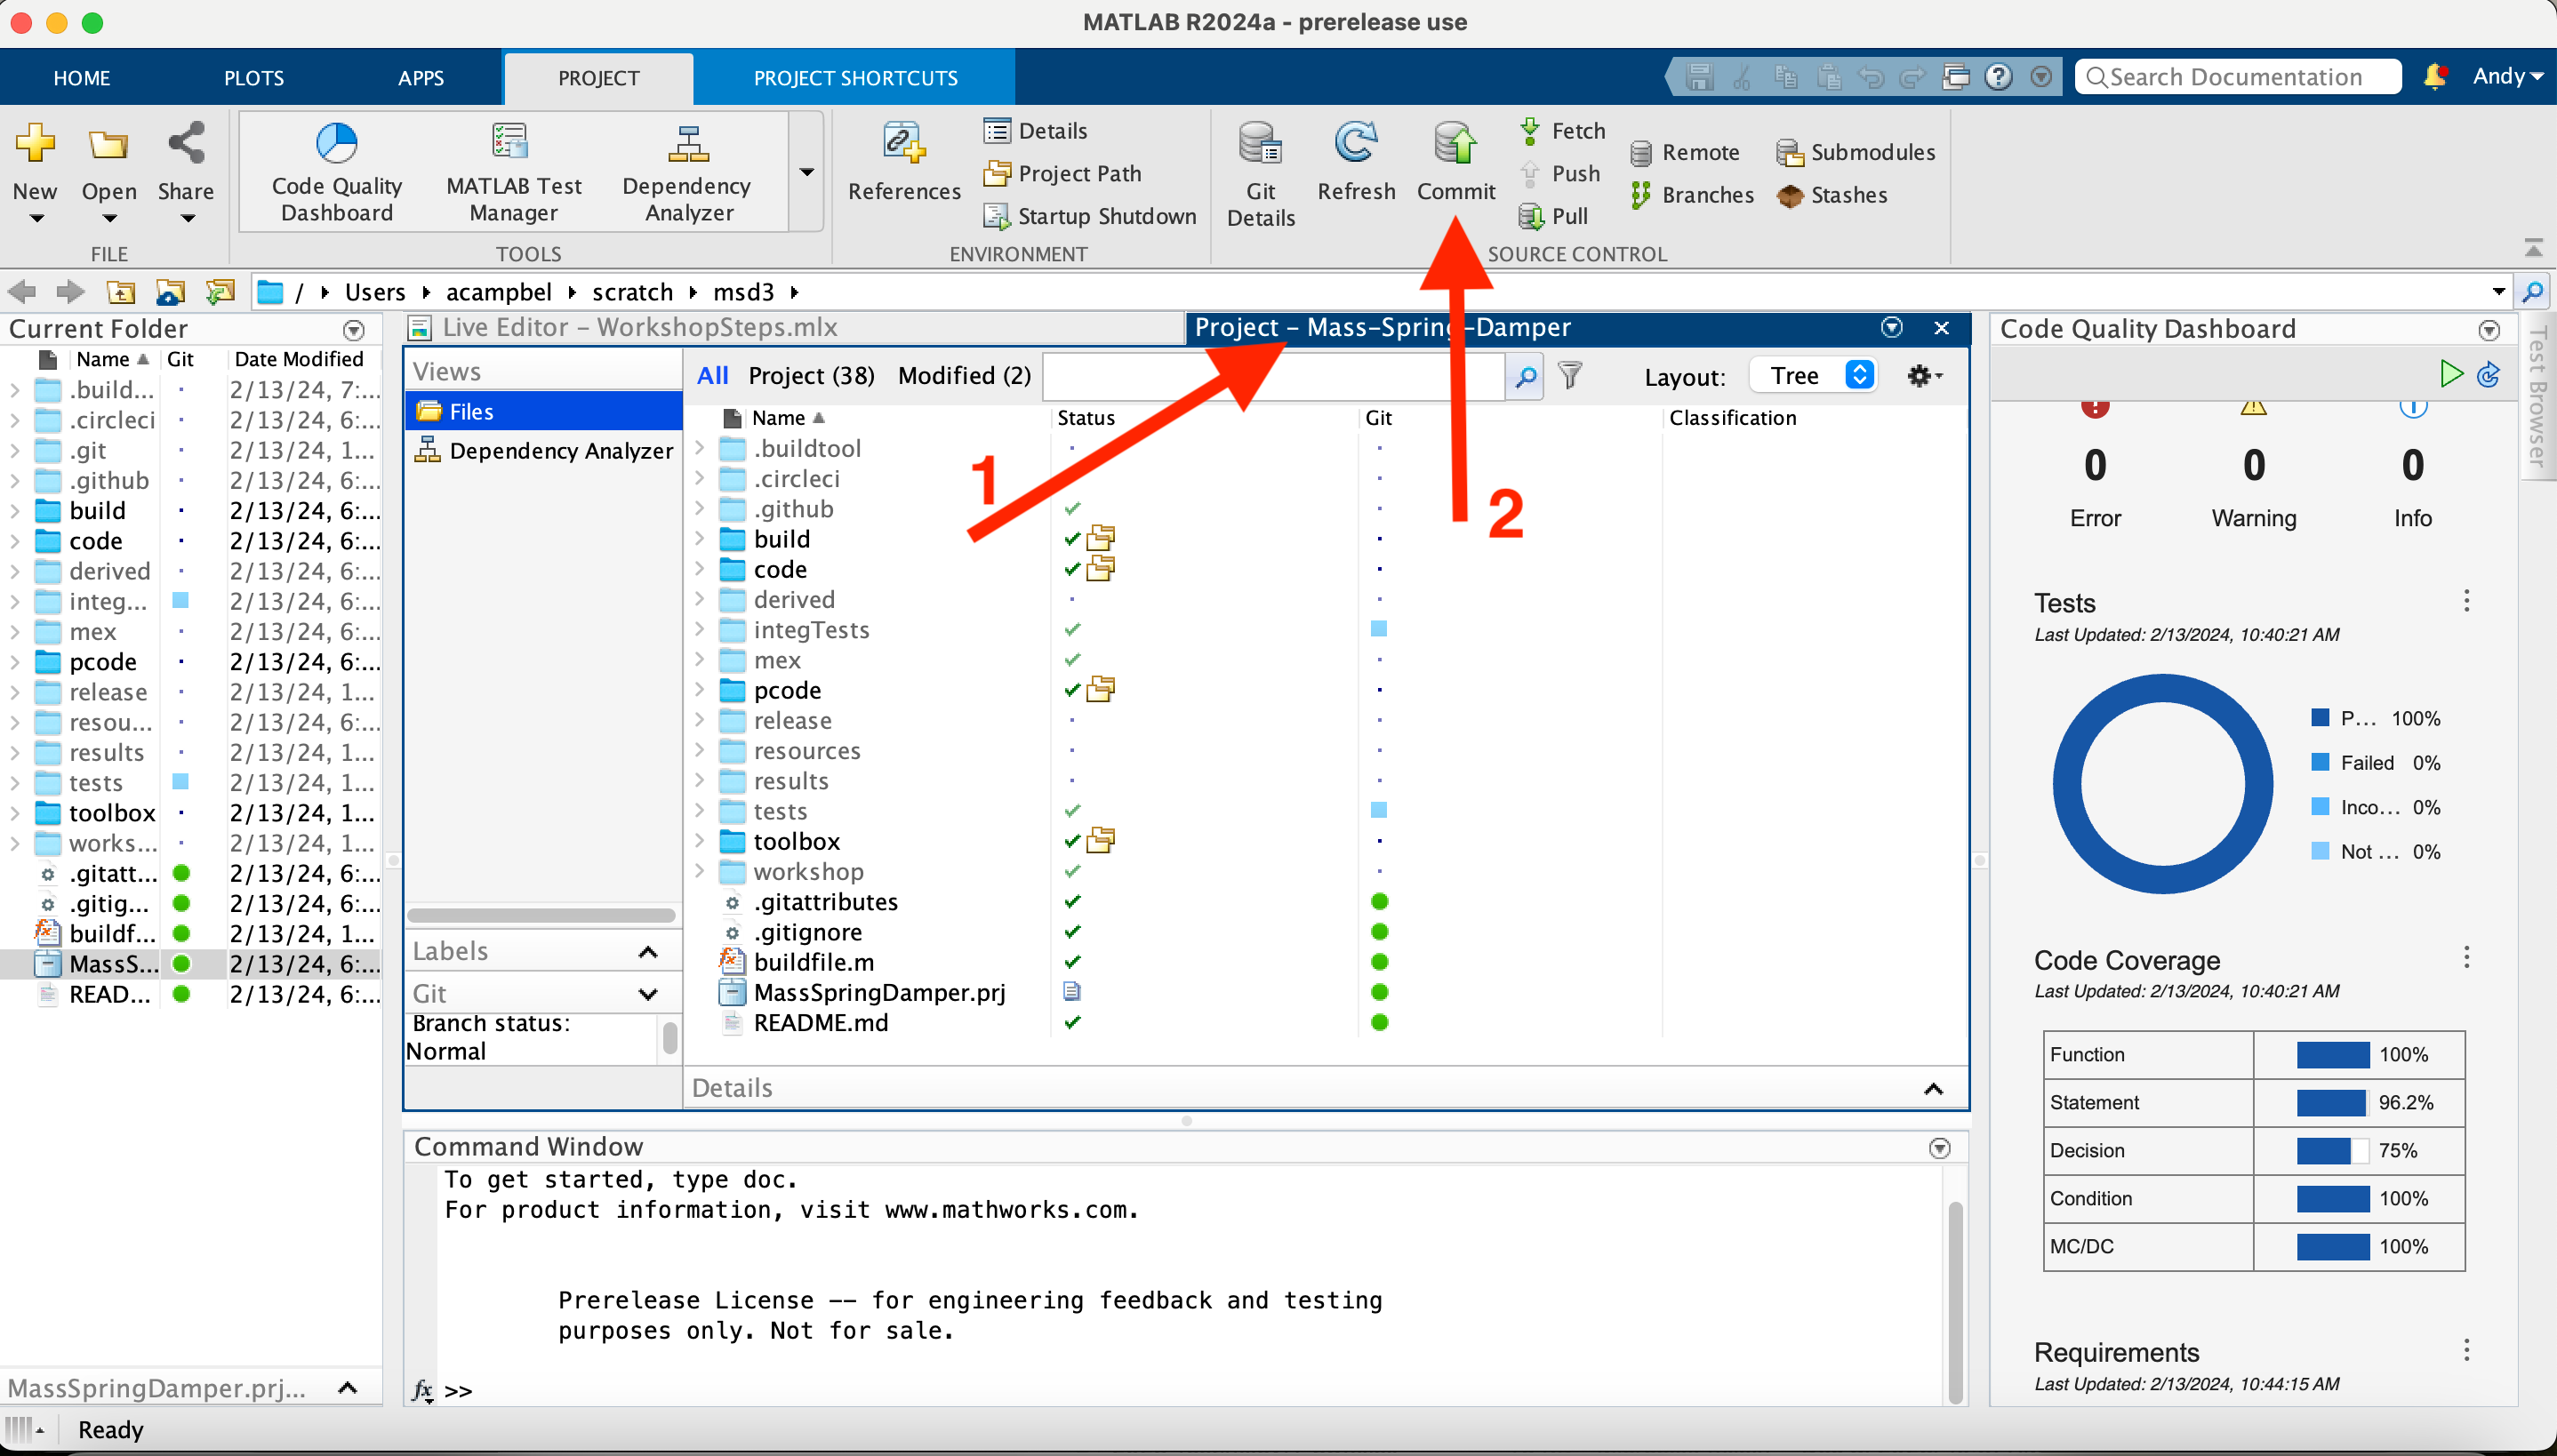

...and in a nice commit message ...

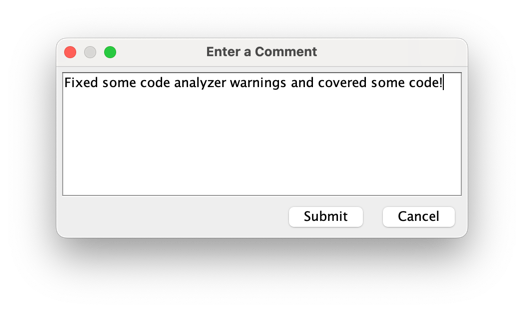

...and then push!

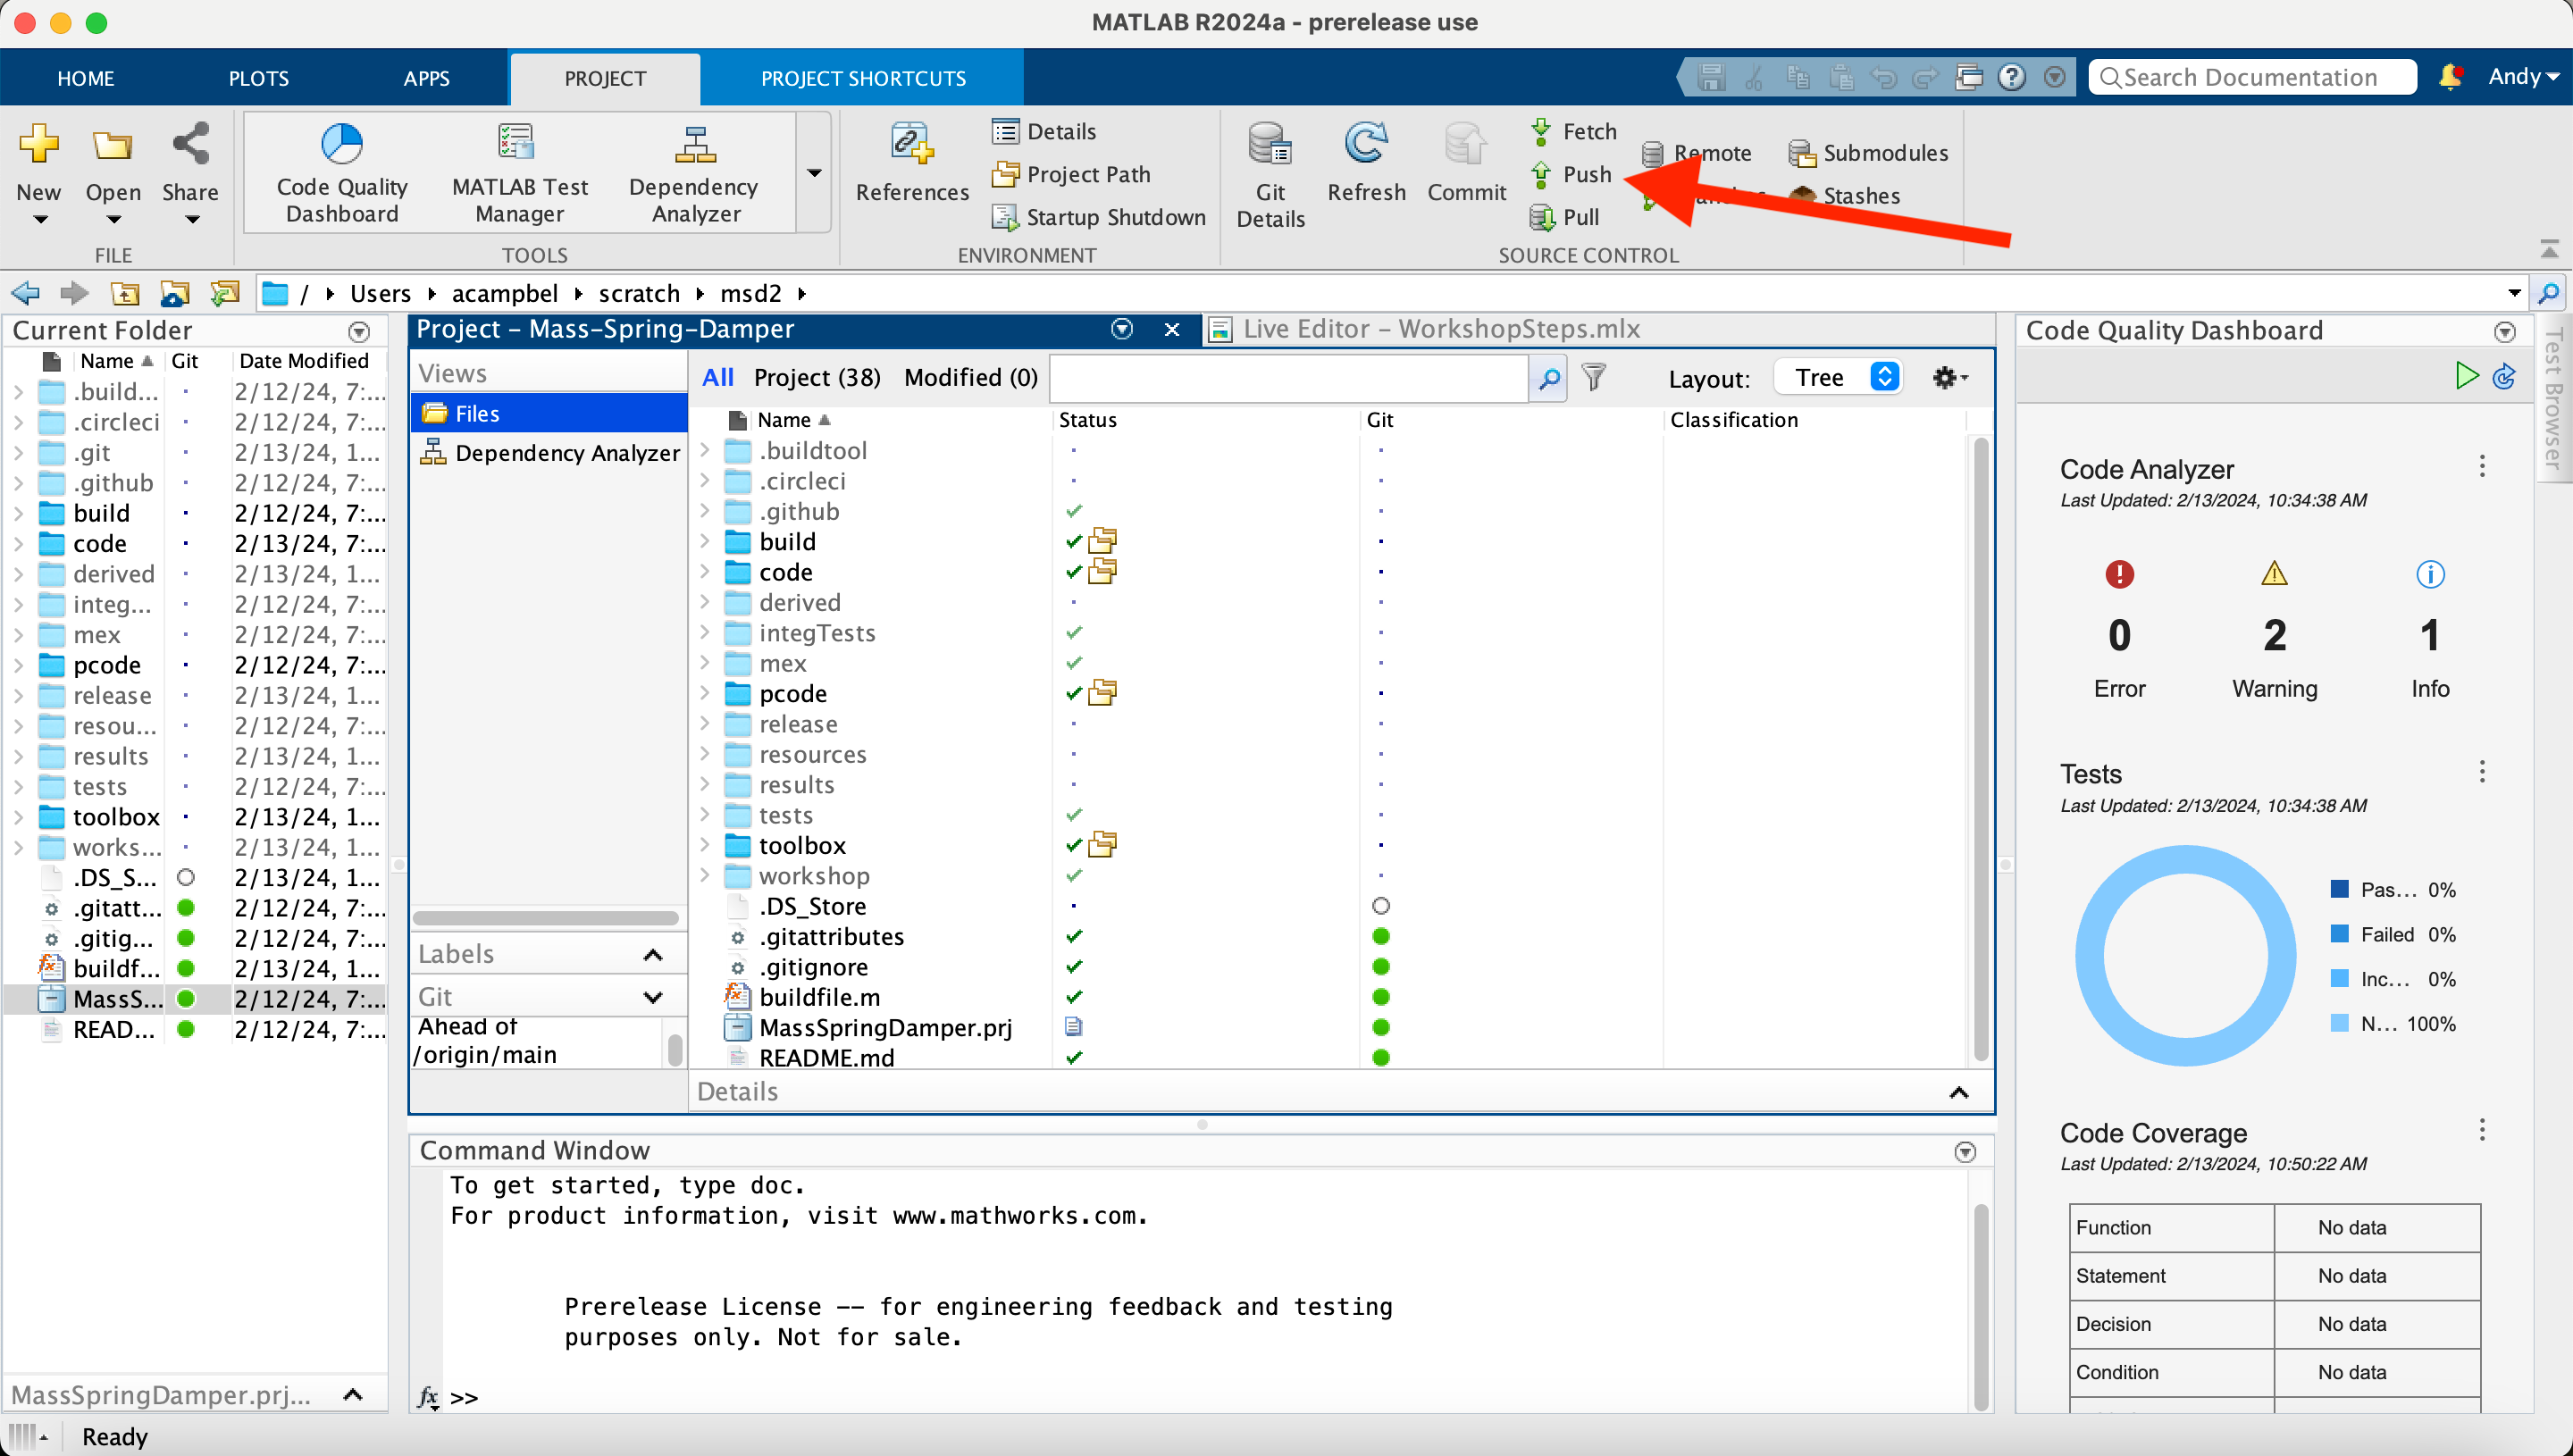

Now we can see the GitHub Actions going. Go back to your web browser and go to your forked repository. You will see your commit message at the top of your code listing along with an orange dot. This orange dot is indicating progress with your build. To see what is happening, click the Actions tab.

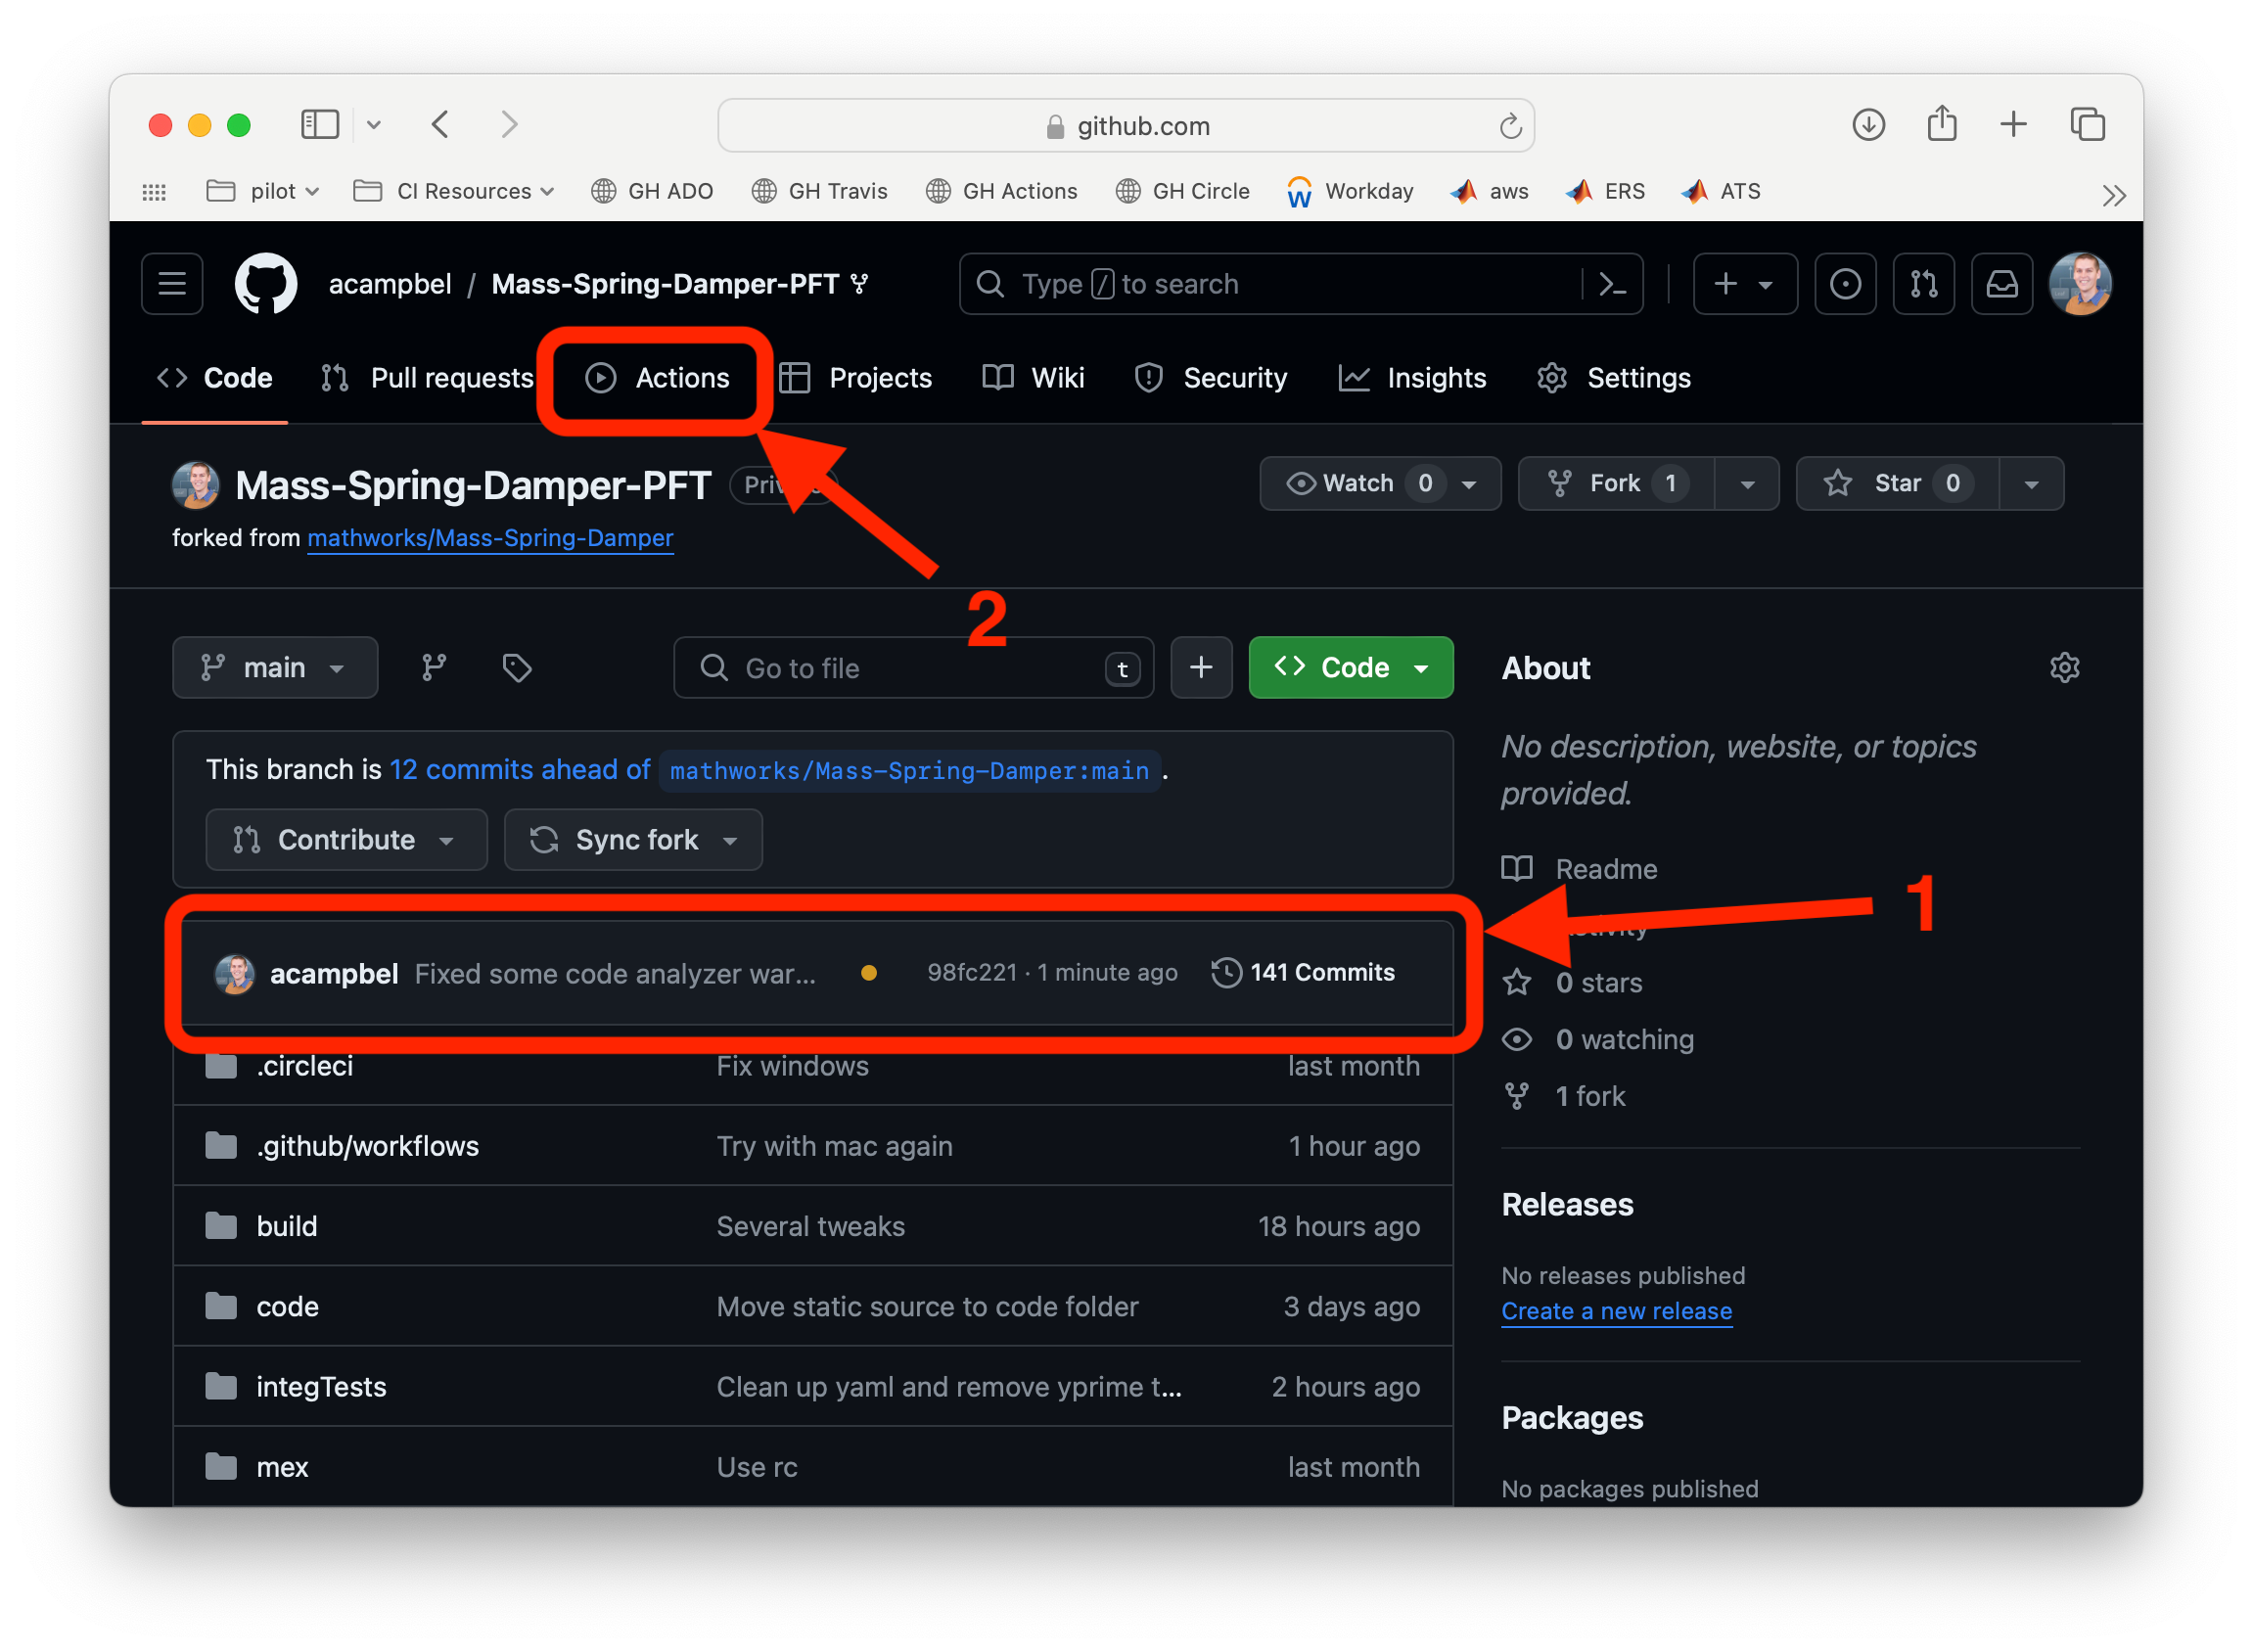

Here your job is running at the top of the list. Click through that job to see more of what is going on:

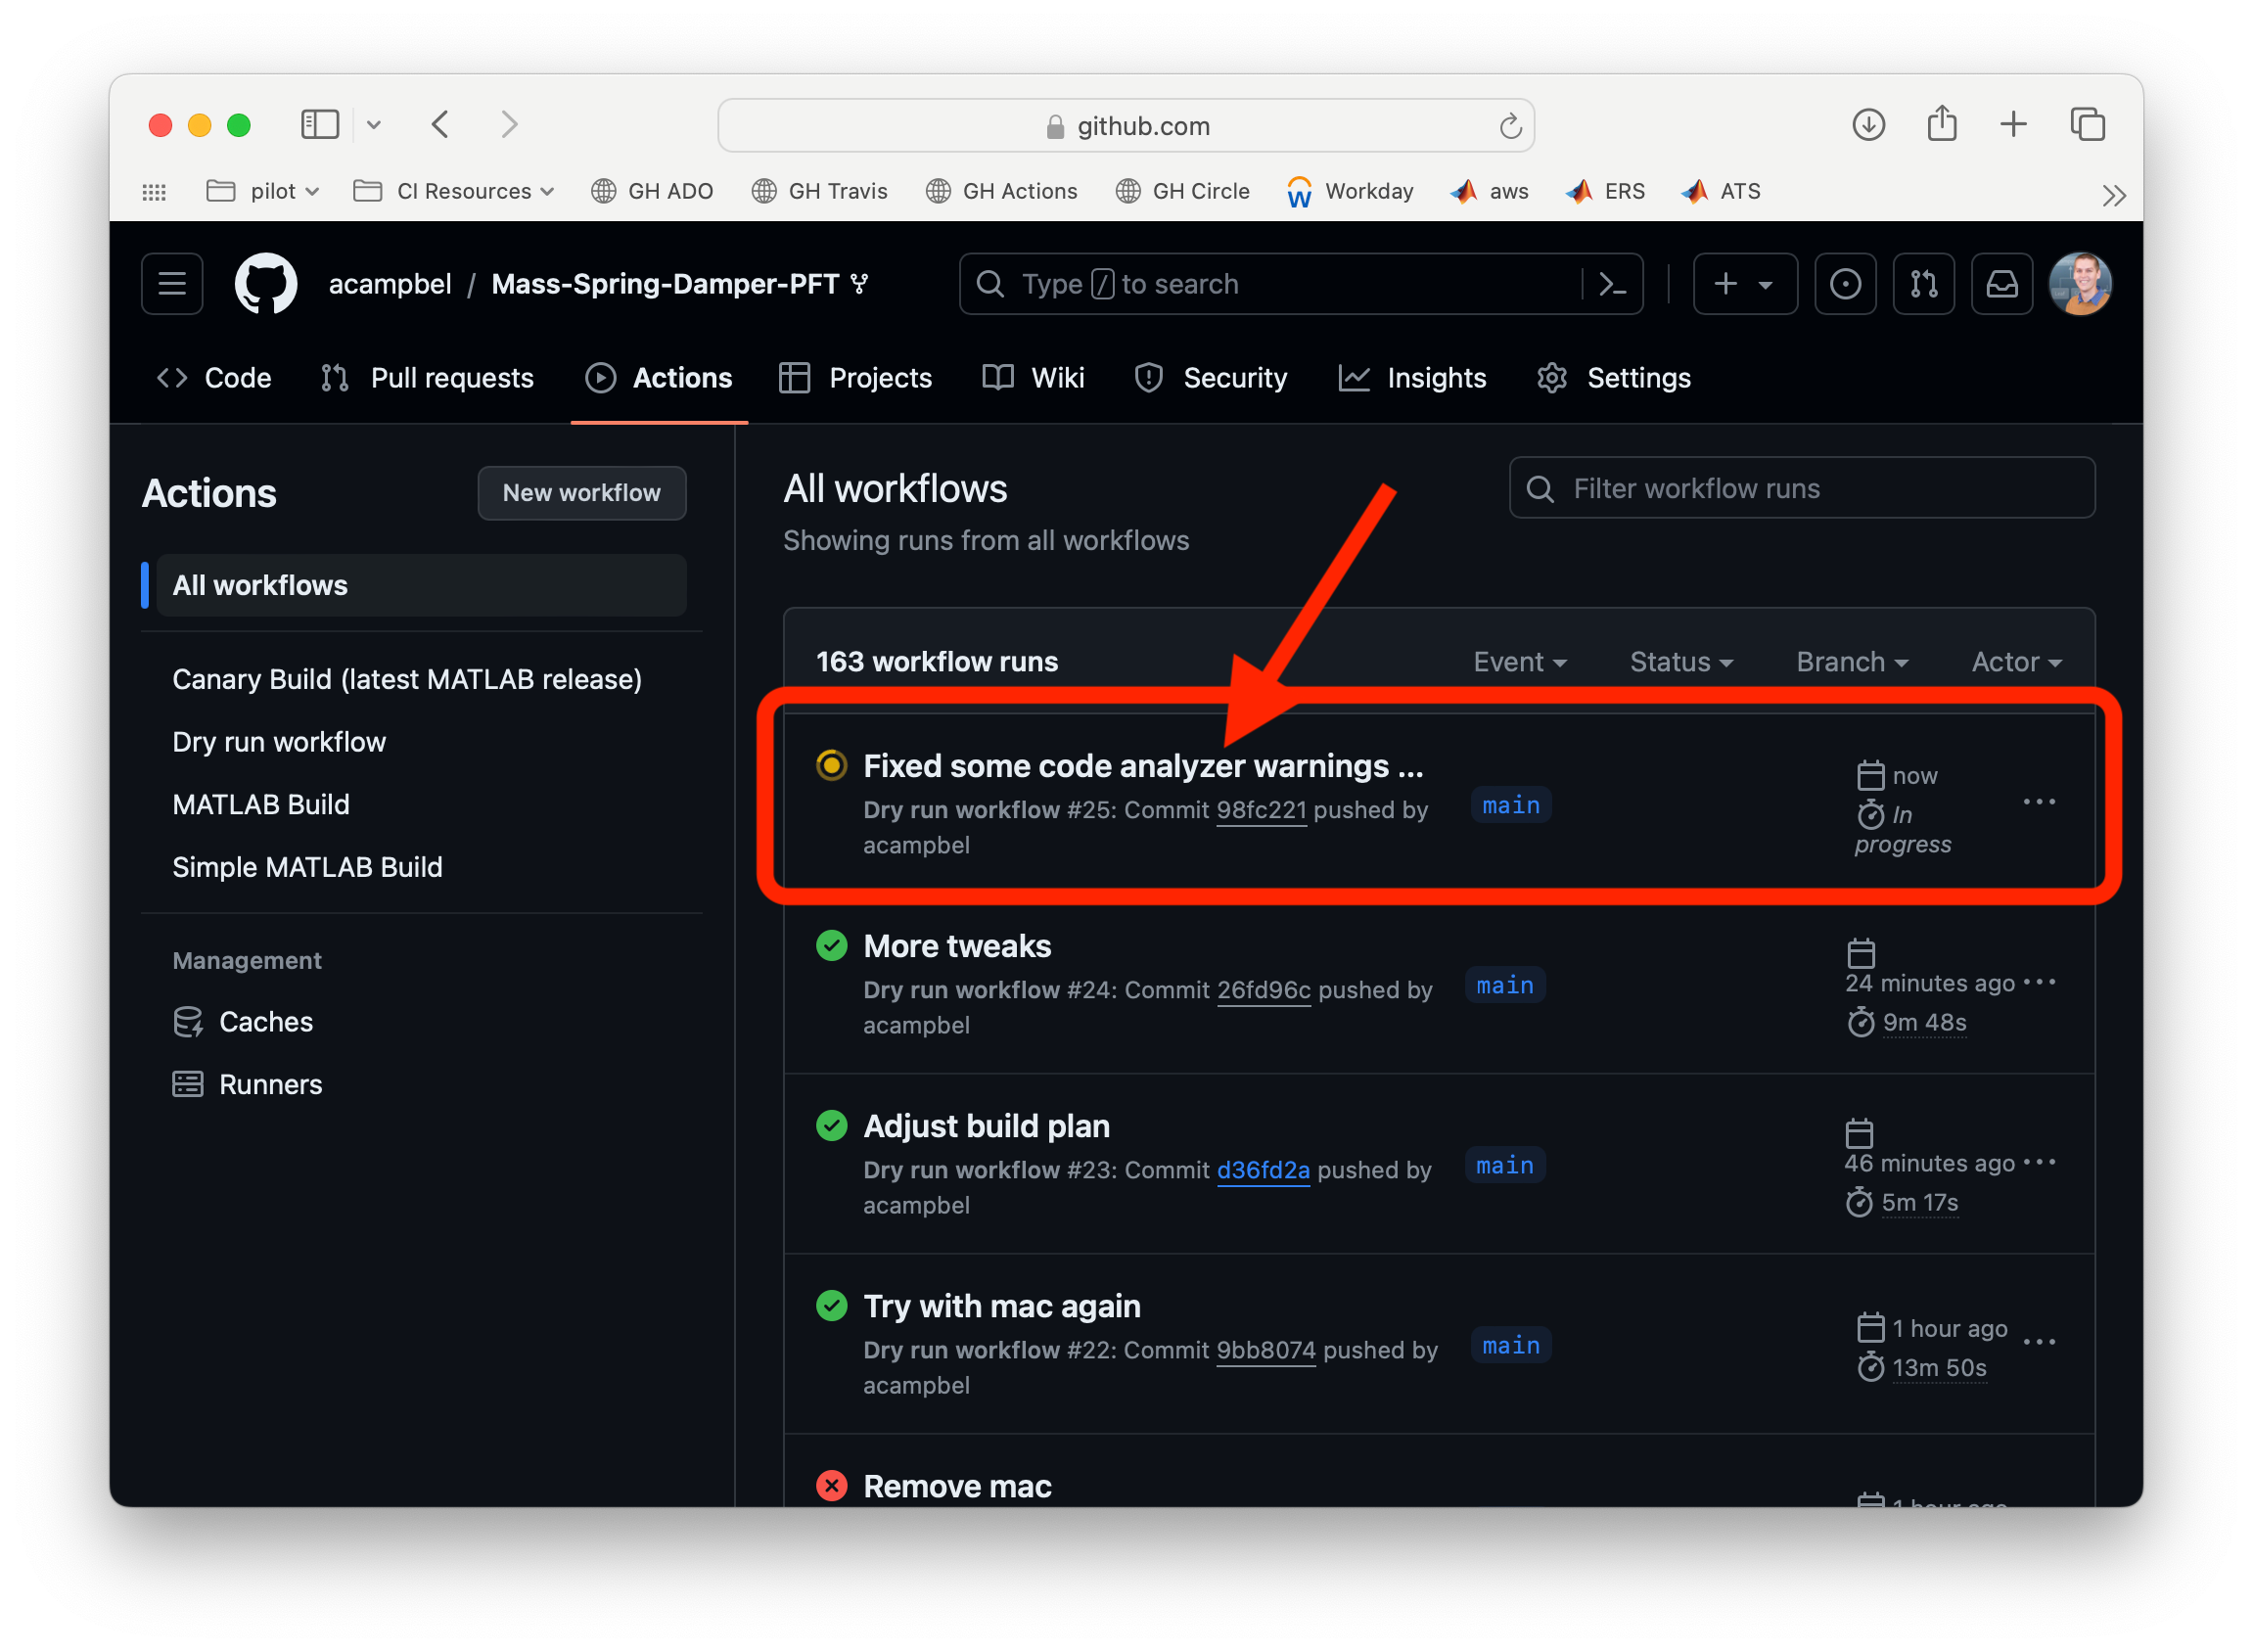

This will bring you to the Job Summary page. Here you can see that GitHub has spun up 3 machines for you for each platform. (TODO: New screenshot with windows build running). You don't need ot worry about how it is orchestrated. You don't need to create and manage a Docker image. GitHub manages the infrastructure for you and the `matlab-actions `GitHub actions takes care of getting MATLAB on the machines that they spin up. Taking a look at one of those jobs you can see that the setup process took about 1 minute and half (once cached), and you can expand the tree to observe the build:

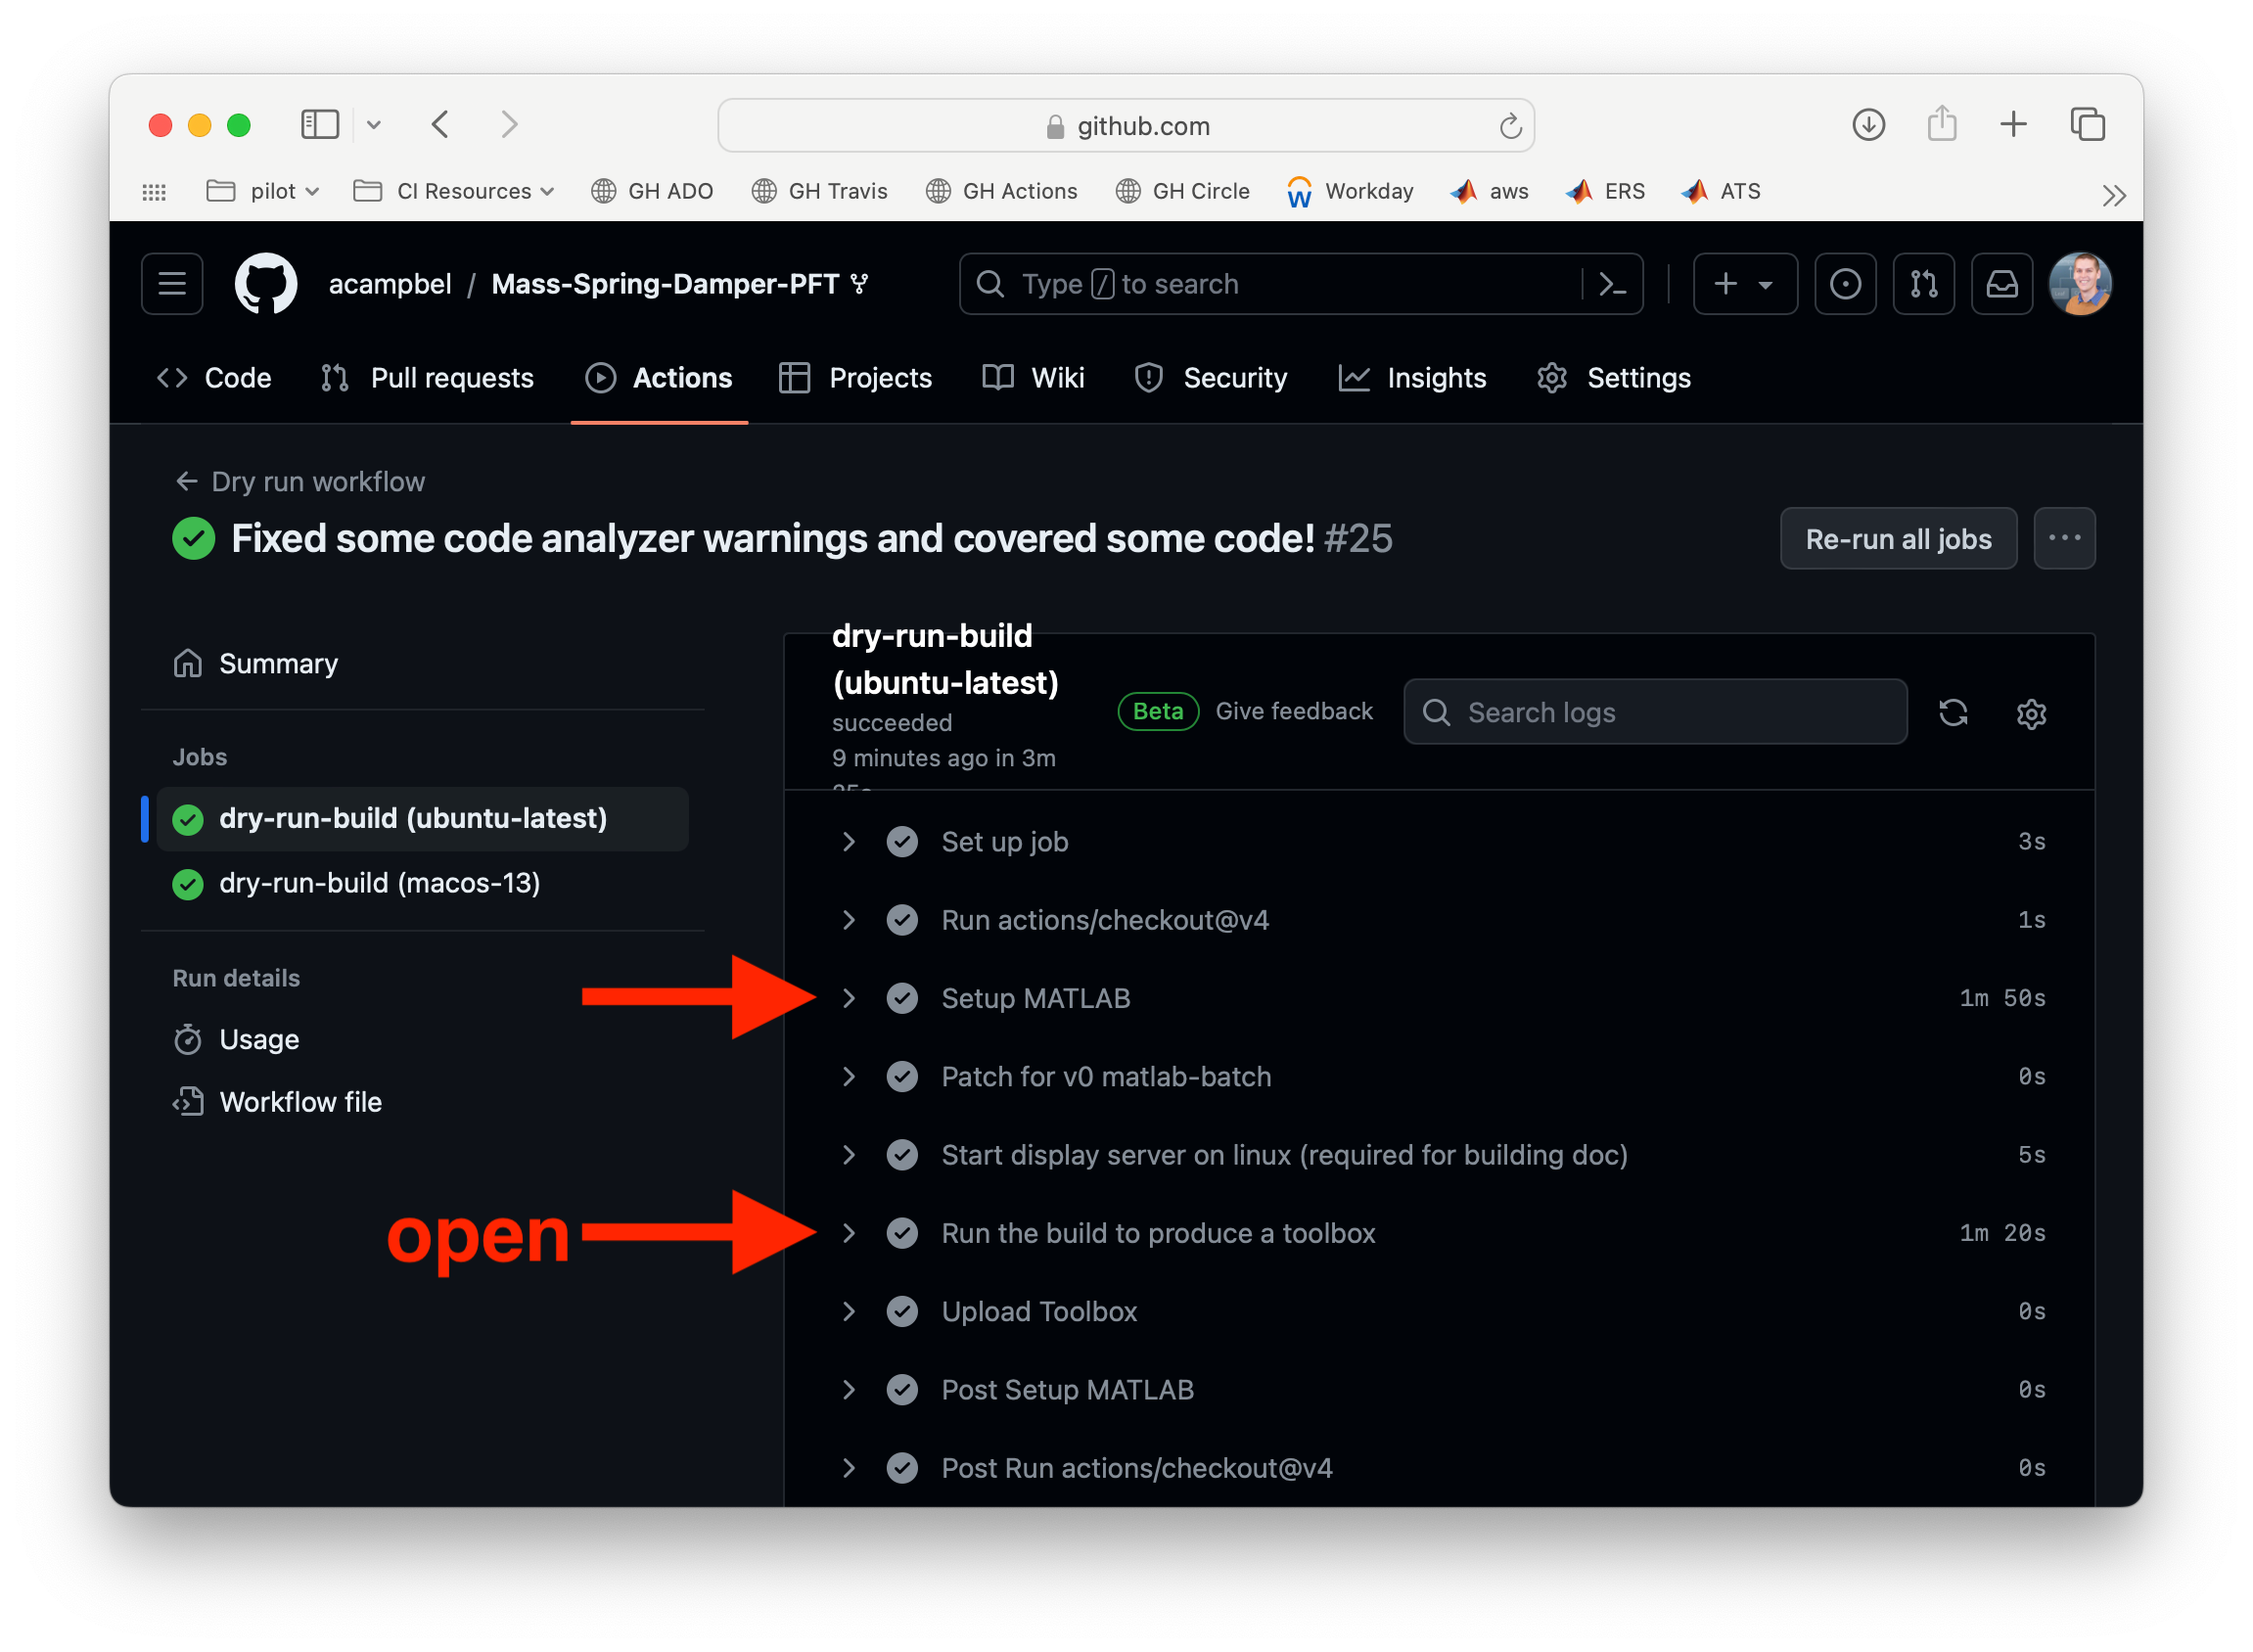

The build should look familiar! It should look just like what we ran as part of our local build process. And that's because it is! Using the build framework both locally and in CI enable you to develop locally in the same way the build occurs on the CI system. What is different here is that it is going through that process on mutliple platforms simultaneously. For generating toolboxes, this is particularly useful as you need to build MEX files on all platforms you want to support with the toolbox.

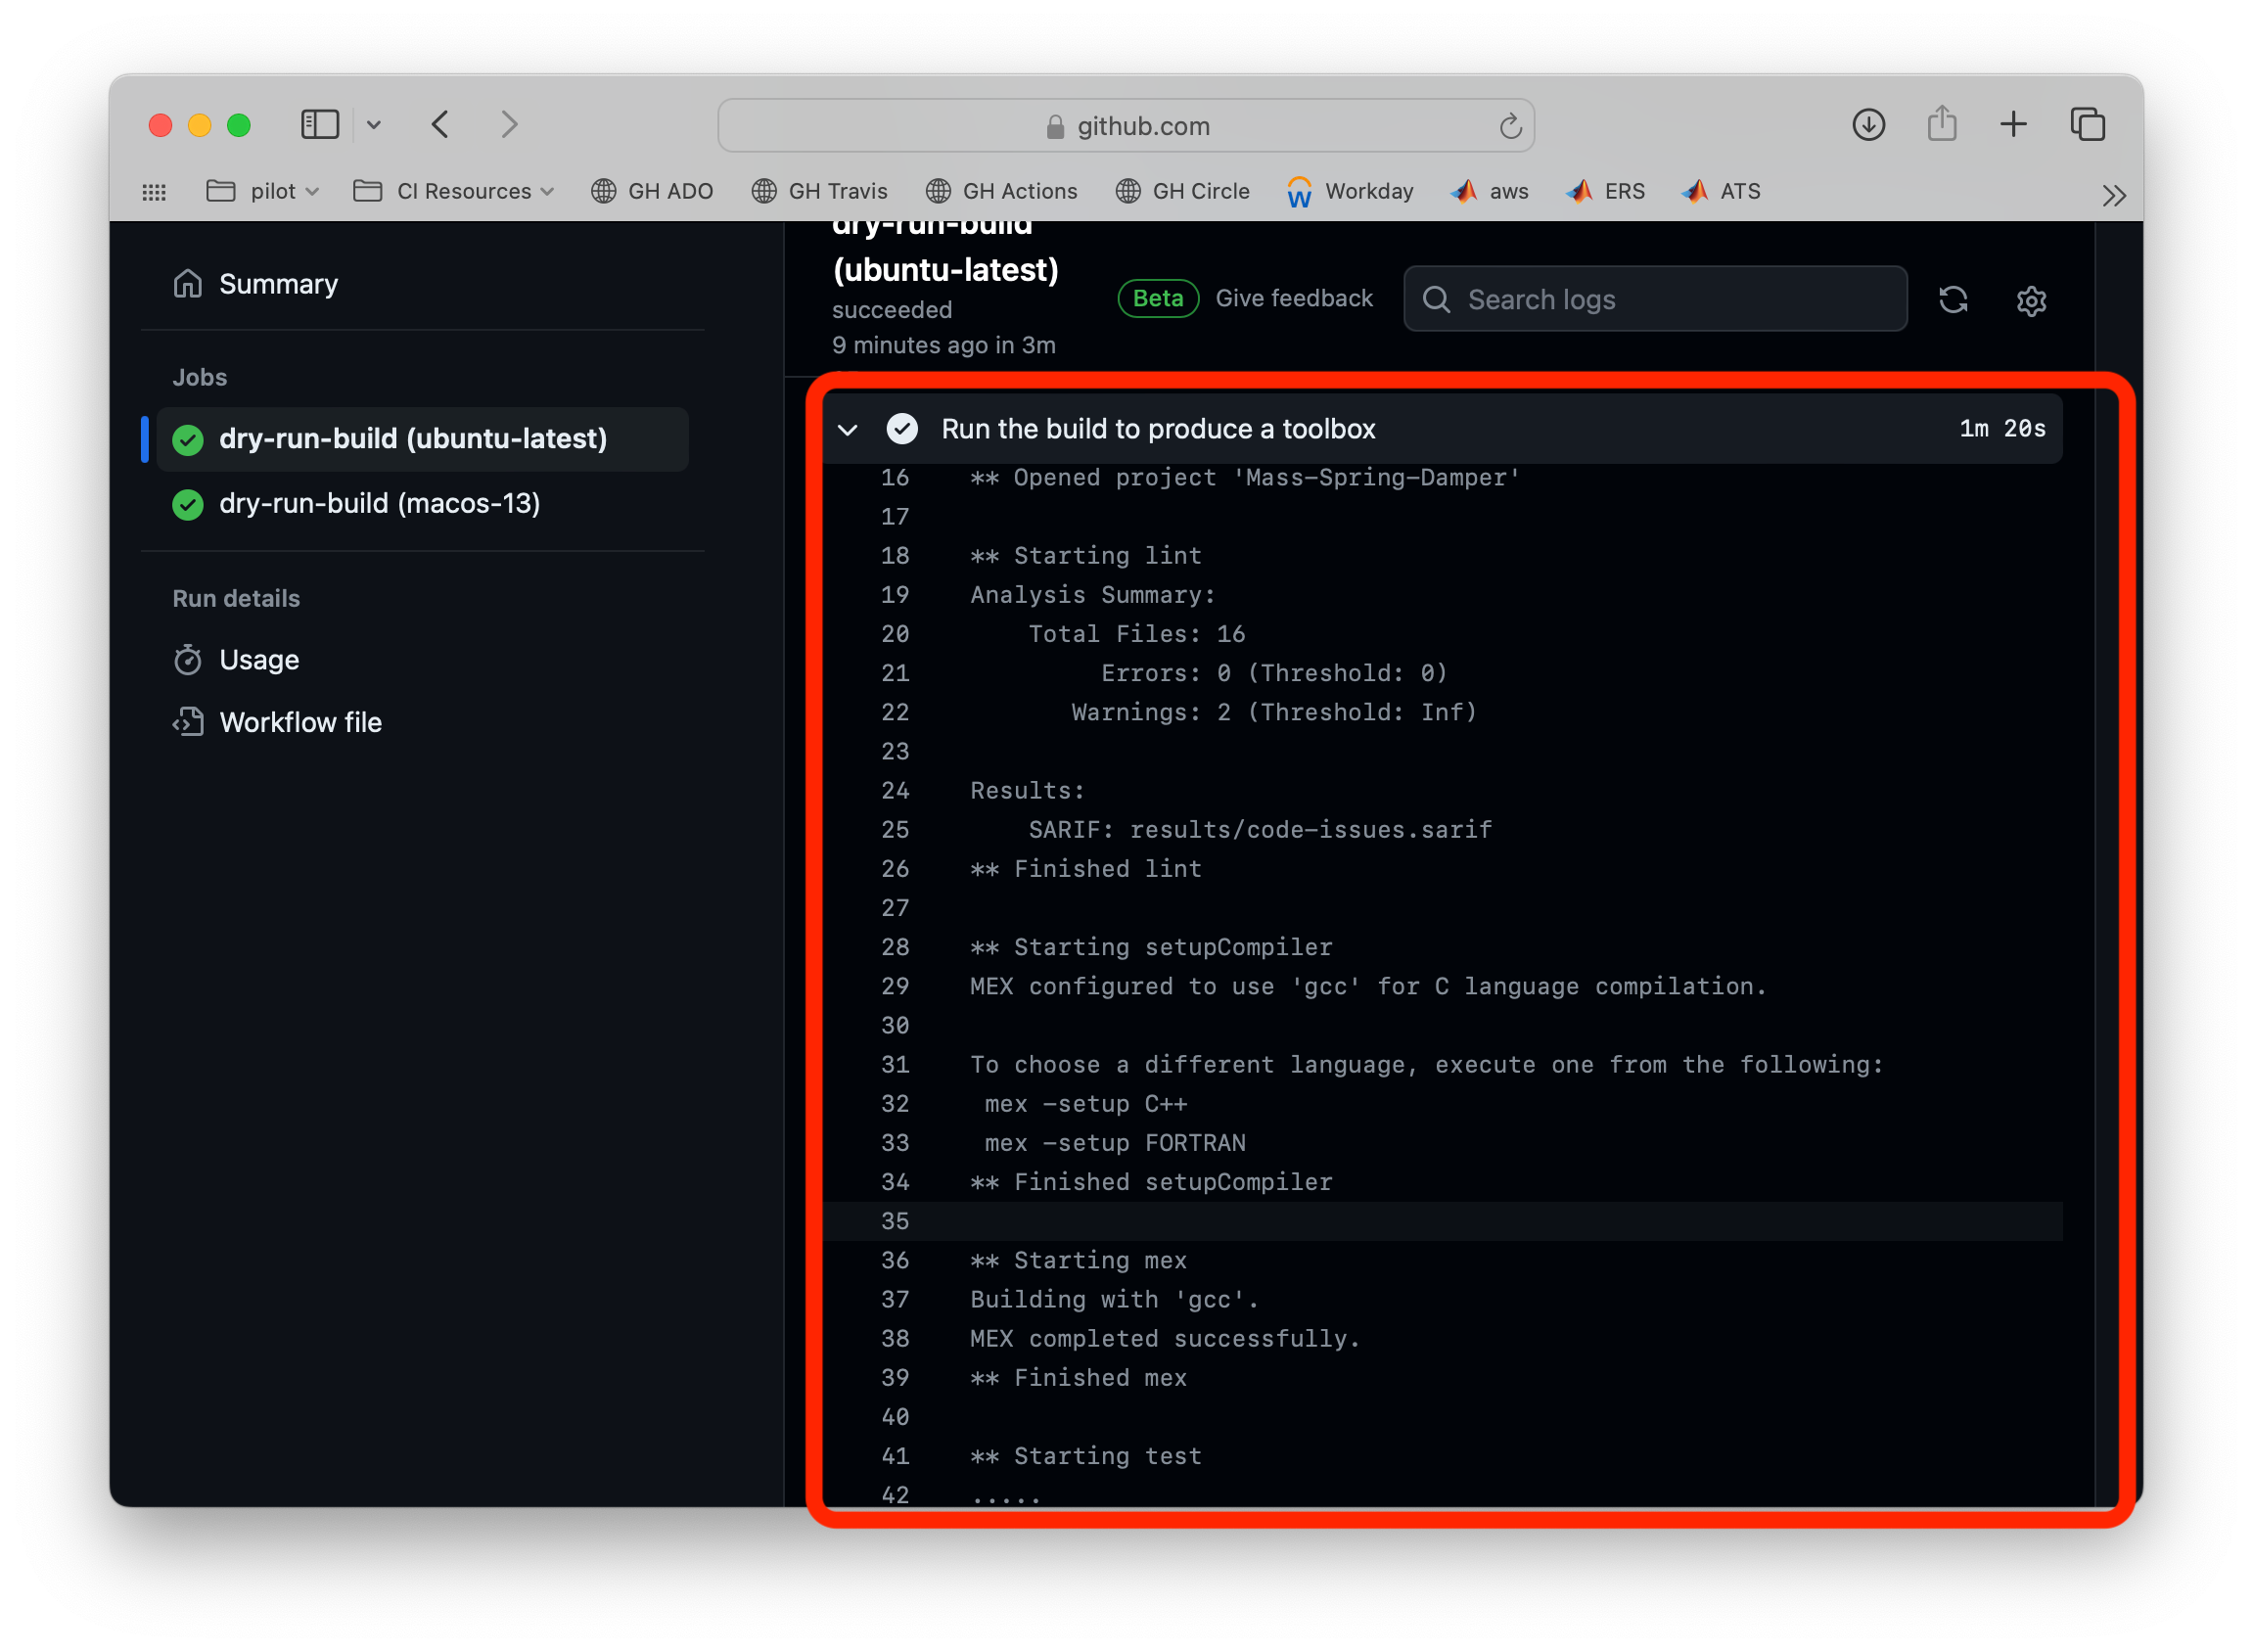

open Chapter_5

#### [Preface & TOC](matlab:open('index.html')) | [Chapter 5](matlab:open('Chapter_5.html'))